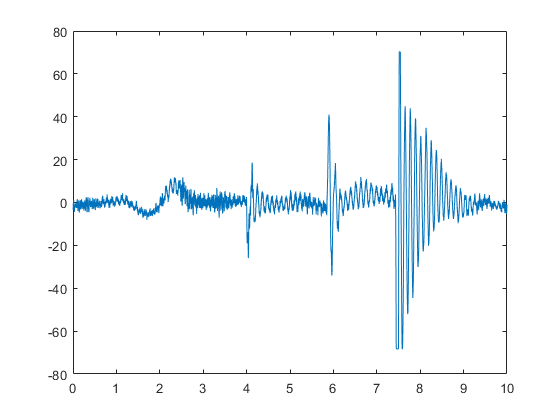

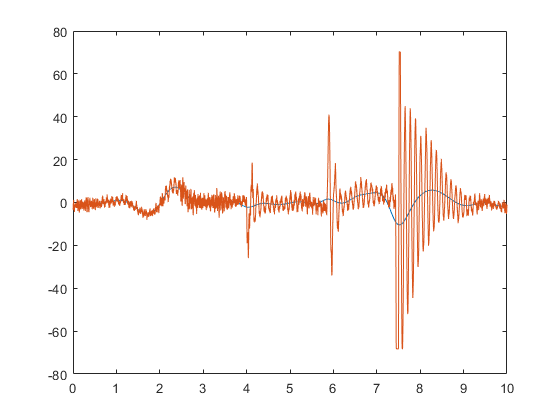

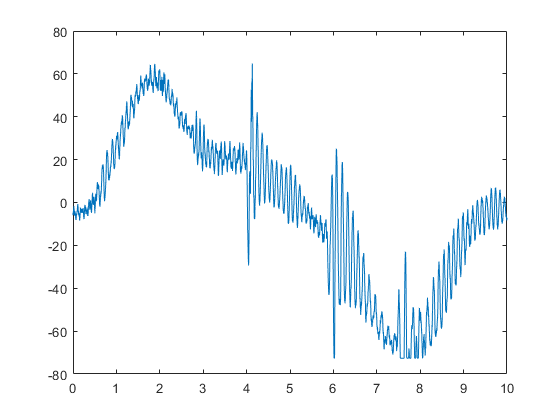

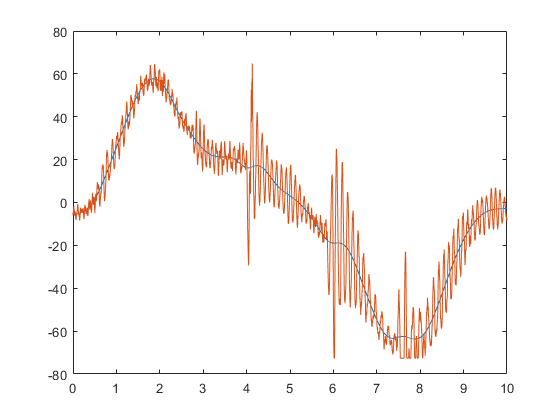

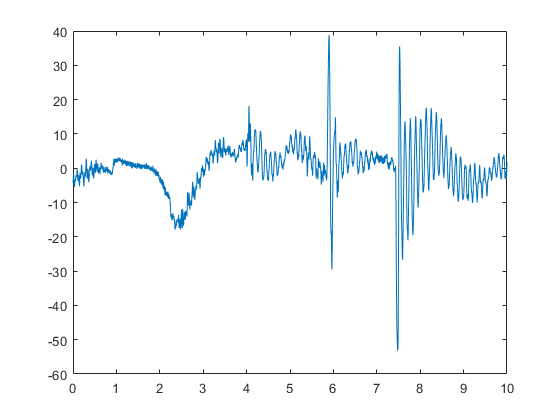

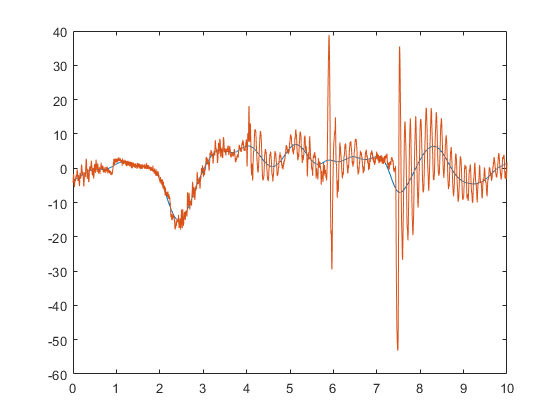

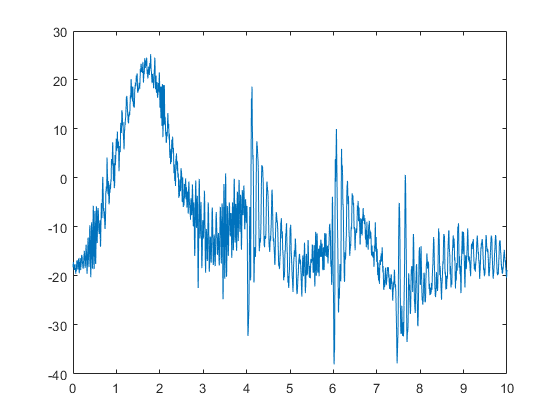

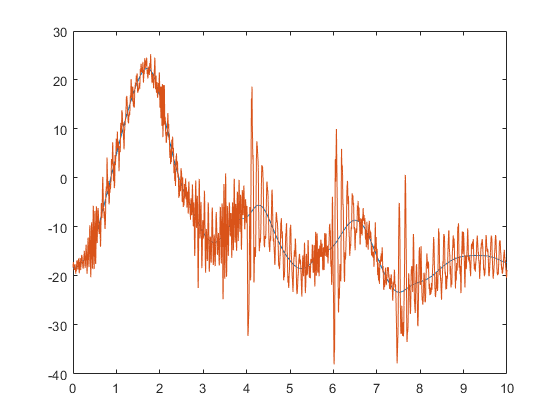

% t=0:0.001:13.408;
% for i=1:7
%      figure(i)
%     plot(m,y(:,i))
%     hold on
%     plot(t,A(200:13608,i+7))
% %     figure(i+7)
% %       plot(t,A(200:13608,i))
% end
% % t=0:0.025:13.408;
% % for i=1:7
% %      figure(i)
% %     plot(m,y(:,i))
% %     hold on
% %     plot(t,A(200:25:13608,i+7))
% %     figure(i+7)
% %       plot(t,A(200:25:13608,i))
% % end

% fk=100  %采样频率
% N=1024  %采样个数
% n=-N/2:N/2-1
% f=n*fk/N
% t=n/fk
% y=sin(2*pi*40*t)
% fft_y=fft(y);
% fftshift_y=fftshift(fft_y);
% f=linspace(-50,50,1024);
% plot(f,abs(fftshift_y));
% [g,Wn]=buttord(0.4,0.6,1,30)
% [b,a]=butter(g,Wn)
%  [q,w]=freqz(b,a,256);
%  fs=30;
%  plot(w*fs/(2*pi),abs(q))
%  k=filter(b,a,y);
%  fft_k=fft(k);
%  fftshift_k=fftshift(fft_k);
%  plot(f,abs(fftshift_k));
load A
t=0:0.001:10;
fn=1000;%采样频率
ap=1;%通带最大衰减
as=50;%阻带最大衰减

wp=1;%通带截止频率
ws=10; %阻带截止频率

wpp=wp/(fn/2);
wss=ws/(fn/2); %归一化;
[n wn]=buttord(wpp,wss,ap,as) ;%计算阶数截止频率
[b a]=butter(n,wn);%计算N阶巴特沃斯数字滤波器系统函数分子、分母多项式的系数向量b、a。
for i=1:7
    mmyy(:,i)=filtfilt(b,a,A(:,i)); %滤波b、a滤波器系数，my滤波前序列
end
% t=0:0.001:13.408;
for i=1:7
    figure(i);
    plot(t,A(200:10200,i));
    figure(i+7);
    plot(t,mmyy(200:10200,i));
    hold on
    plot(t,A(200:10200,i));
%     figure(i+14)
%     plot(t,mmyy(200:10200,i));
end